# Plot Root locus with Asymtotes

clear all

## Generate a System

s = tf('s');
%Some examples

%PTn - no  zeros, select n
G = tf(1,1);  ord  =3;
 for i = 1:ord
 G = G /(s+i);
 end

% Allpass
%G=(s+1)/(s-1)

% 3. order oscillatory
%G = (s+1)*(s+5)/(s+10)/(s+1+3i)/(s+1-3i);

% 5. order oscillatory with kk zeros
%G = (s+1+3i)*(s+1-3i)/(s-1+3i)/(s-1-3i)/(s+3+i)/(s+3-i)/(s+5);

% PZ describtion
G = zpk(minreal(G))


G =
 
          1
  -----------------
  (s+3) (s+2) (s+1)
 
Continuous-time zero/pole/gain model.



% Poles & Zeros:
p = pole(G)

p =    -3.0000
   -2.0000
   -1.0000


z = zero(G)


z =

  0×1 empty double column vector



## Plot Root Locus

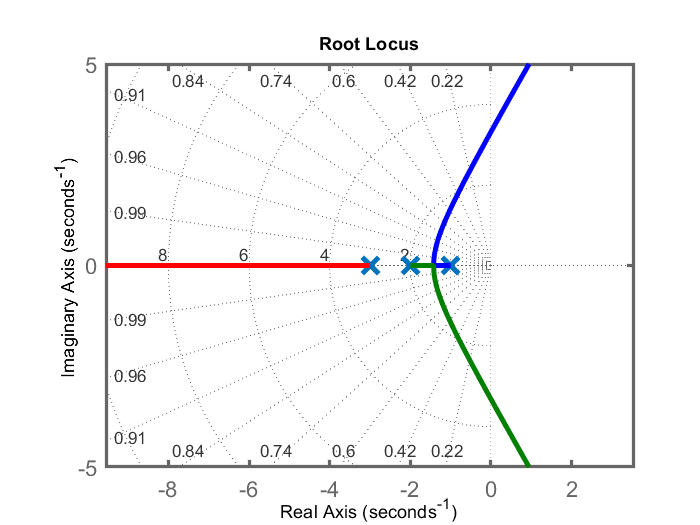

figure(1); rlocus(G); hold on;

% Visulas:
axis equal; grid on
h=gca; h.LineWidth = 2; h.FontSize =13;
num = length(h.Children(1).Children);

for i = 1:num
    h.Children(1).Children(i).MarkerSize =14;
    h.Children(1).Children(i).LineWidth =3;
end

## Calculate and plot Asymptotes

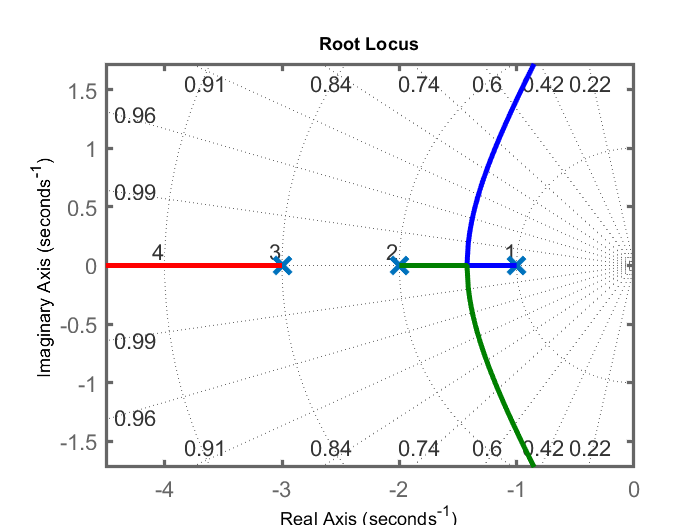

figure(2); rlocus(G); hold on;
%axis equal; 

% Visuals:
grid on
h=gca; h.LineWidth = 2; h.FontSize =13;
num = length(h.Children(1).Children);
for i = 1:num
    h.Children(1).Children(i).MarkerSize =14;
    h.Children(1).Children(i).LineWidth =3;
end
sc = 1.5;
if isempty(z) & length(p)>1
    h.XLim = [sc*min(real(p)),sc*max([real(p);0])];
elseif isempty(z) == 0
    h.XLim = [min(sc*min(real(p)),sc*min(real(z))), max([sc*max(real(p)),sc*max(real(z)),0])];   
end
h.YLim=[-1,1];
axis equal

#### Calculate Centroid:

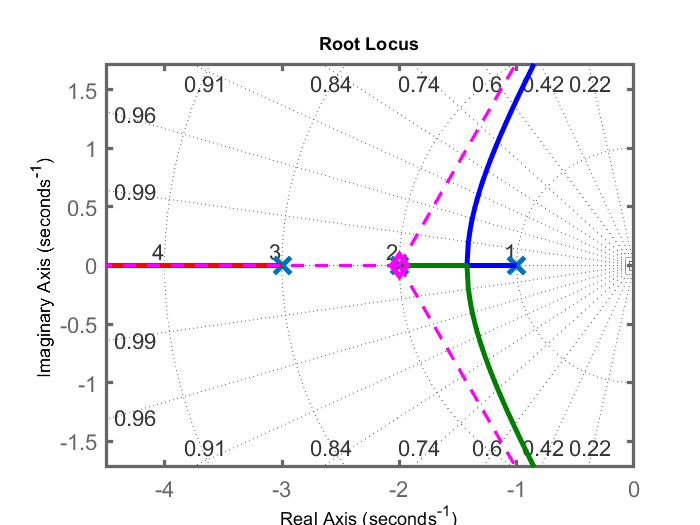

Centroid location on x axis: -2


if length(p)-length(z) == 0
    disp('No Asymptotes as n_p = n_z')
else
    cg = (sum(p) - sum(z))/(length(p)-length(z)); %Equation for Centroid using poles and zeros
    rl  =rlocus(G);
    indx_Ainf = find(rl(:,end)==Inf);  % Check index in rl coordinates when Matlab considers curves to reach  in infinity
    
    % Plot Asymptotes
    for i = 1:length(indx_Ainf)
        plot([cg real(rl(indx_Ainf(i),end-1)) ], [0, imag(rl(indx_Ainf(i),end-1)) ], 'm--', 'Linewidth',2)
    end
    % Plot centroid 
    plot(cg,0,'md', 'LineWidth', 3, 'MarkerSize',10)  
    disp(['Centroid location on x axis: ',num2str(cg)])
end